# **Affichage des angles calculés et comparaison des populations avec SPM1D**

**Affichage de l'angle huméro-thoracique pour une popluation choisie**

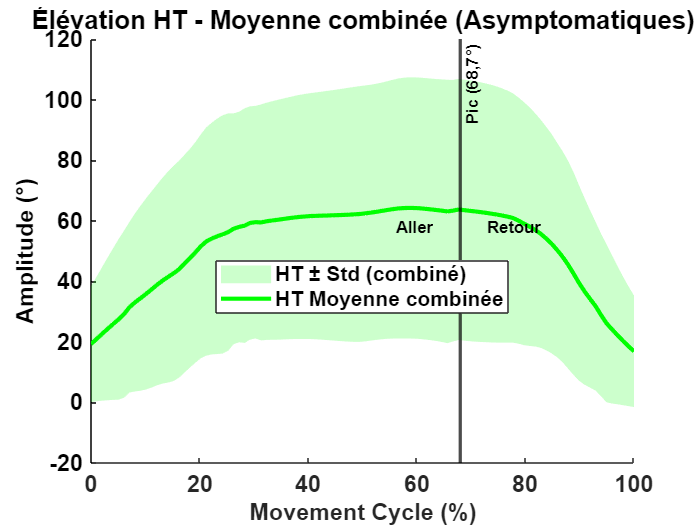

% === Données cinématiques : Élévation HT (asymptomatiques) === 
load('all_angles_statistics_Asymptomatic.mat');

x_new = linspace(0, 100, 100);

% Données droite
right_mean = all_data.combined.right.HT.Elevation_globale.mean_deg;
right_std = all_data.combined.right.HT.Elevation_globale.std_deg;

% Données gauche
left_mean = all_data.combined.left.HT.Elevation_globale.mean_deg;
left_std = all_data.combined.left.HT.Elevation_globale.std_deg;

% Moyenne combinée (moyenne arithmétique)
combined_mean = (right_mean + left_mean) / 2;

% Écart-type combiné (moyenne quadratique pour la zone d’incertitude)
combined_std = sqrt((right_std.^2 + left_std.^2) / 2);

% === Affichage de la courbe combinée ===
figure;
hold on;
title('Élévation HT - Moyenne combinée (Asymptomatiques)', 'FontSize', 18, 'FontWeight', 'bold');

% Axe principal
yyaxis left
set(gca, 'YColor', 'k', 'FontSize', 14, 'FontWeight', 'bold');

% Zone d’incertitude combinée (± std)
fill([x_new fliplr(x_new)], ...
     [combined_mean' + combined_std' fliplr(combined_mean' - combined_std')], ...
     'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none'); % magenta clair

% Courbe moyenne combinée
plot(x_new, combined_mean, 'g-', 'LineWidth', 2.5);

% Ligne verticale de référence + annotations
pourcentage_X = 68;
xline(pourcentage_X, 'k-', 'Pic (68,7°)', 'LineWidth', 2, 'FontWeight', 'bold');

text(pourcentage_X - 5, max(combined_mean) * 0.9, 'Aller', ...
    'HorizontalAlignment', 'right', 'FontWeight', 'bold');
text(pourcentage_X + 5, max(combined_mean) * 0.9, 'Retour', ...
    'HorizontalAlignment', 'left', 'FontWeight', 'bold');

% Axes
xlabel('Movement Cycle (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude (°)', 'FontSize', 14); 
legend({'HT ± Std (combiné)', 'HT Moyenne combinée'}, 'Location', 'best');

% Supprimer l’axe droit
yyaxis right
set(gca, 'YColor', 'none'); 
ylabel('');

**Comparaison asymtomatique vs post**

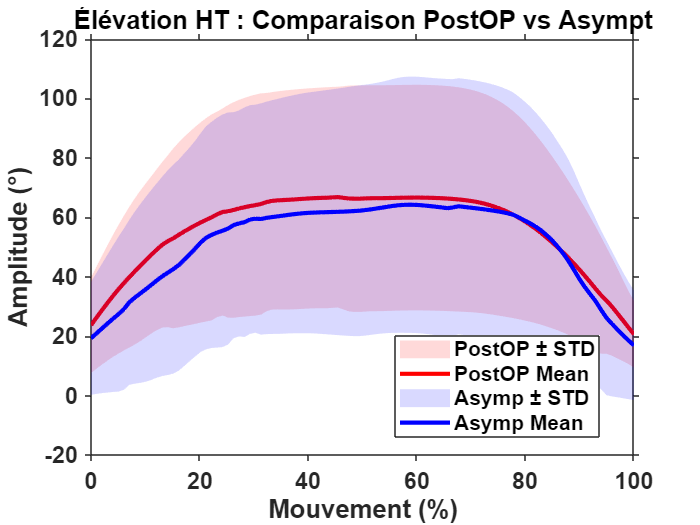

% === Chargement des deux jeux de données === 
load('all_angles_statistics_Post_operatoire.mat'); % Données PostOP
postop_data = all_data;

load('all_angles_statistics_Asymptomatic.mat'); % Données Asymptomatiques
asymp_data = all_data;

x_new = linspace(0, 100, 100);

% === Moyennes combinées droite + gauche ===

% PostOP
postop_right_mean = postop_data.combined.right.HT.Elevation_globale.mean_deg;
postop_right_std  = postop_data.combined.right.HT.Elevation_globale.std_deg;

postop_left_mean = postop_data.combined.left.HT.Elevation_globale.mean_deg;
postop_left_std  = postop_data.combined.left.HT.Elevation_globale.std_deg;

postop_mean = (postop_right_mean + postop_left_mean) / 2;
postop_std  = (postop_right_std + postop_left_std) / 2;

% Asymptomatiques
asymp_right_mean = asymp_data.combined.right.HT.Elevation_globale.mean_deg;
asymp_right_std  = asymp_data.combined.right.HT.Elevation_globale.std_deg;

asymp_left_mean = asymp_data.combined.left.HT.Elevation_globale.mean_deg;
asymp_left_std  = asymp_data.combined.left.HT.Elevation_globale.std_deg;

asymp_mean = (asymp_right_mean + asymp_left_mean) / 2;
asymp_std  = (asymp_right_std + asymp_left_std) / 2;

% === Affichage combiné ===
figure;
hold on;
title('Élévation HT : Comparaison PostOP vs Asympt', 'FontSize', 18, 'FontWeight', 'bold');

% Zone rouge clair : ± std PostOP
fill([x_new fliplr(x_new)], ...
     [postop_mean' + postop_std' fliplr(postop_mean' - postop_std')], ...
     'r', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

% Courbe moyenne PostOP
plot(x_new, postop_mean, 'r-', 'LineWidth', 2.5, 'DisplayName', 'PostOP Mean');

% Zone bleue clair : ± std Asymp
fill([x_new fliplr(x_new)], ...
     [asymp_mean' + asymp_std' fliplr(asymp_mean' - asymp_std')], ...
     'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

% Courbe moyenne Asymp
plot(x_new, asymp_mean, 'b-', 'LineWidth', 2.5, 'DisplayName', 'Asymp Mean');

% Légendes et axes
xlabel('Mouvement (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude (°)', 'FontSize', 14, 'FontWeight', 'bold');
legend({'PostOP ± STD', 'PostOP Mean', 'Asymp ± STD', 'Asymp Mean'}, 'Location', 'best');

set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out');
box on;

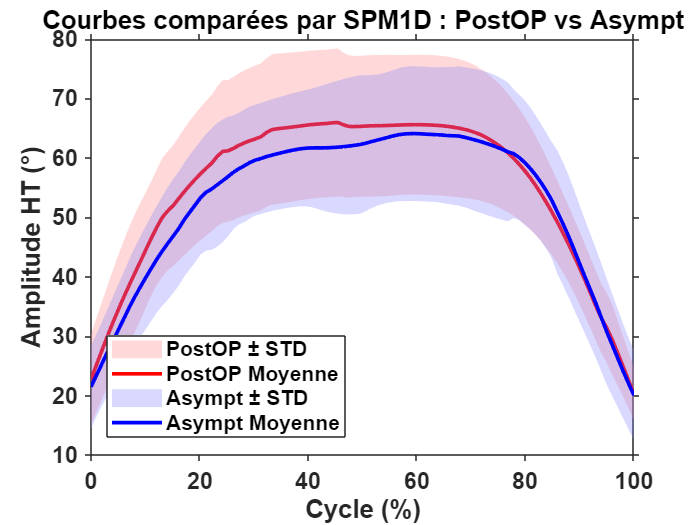


% === Configuration des sujets et côtés analysés ===
asymp_subjects = arrayfun(@(i) sprintf('A%d', i), 1:41, 'UniformOutput', false);
postop_subjects = {'S1','S2','S3','S4','S5','S6','S7','S8','S9','S10','S11','S12','S13'};

% Map côté utilisé pour chaque sujet
sides_asymp = containers.Map( ...
    {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10', ...
     'A11','A12','A13','A14','A15','A16','A17','A18','A19','A20', ...
     'A21','A22','A23','A24','A25','A26','A27','A28','A29','A30', ...
     'A31','A32','A33','A34','A35','A36','A37','A38','A39','A40','A41'}, ...
    {'right','right','left','left','right','left','right','left','left','right', ...
     'left','left','left','left','left','left','left','left','left','left', ...
     'left','left','left','left','left','left','left','left','left','left', ...
     'left','left','left','left','left','left','left','left','left','left','left'});

sides_postop = containers.Map( ...
    {'S1','S2','S3','S4','S5','S6','S7','S8','S9','S10','S11','S12','S13'}, ...
    {'right','right','right','right','left','right','right','left','right','left',...
    'right','right','left'});

% === Initialisation des matrices
HT_data_asymp = [];
HT_data_postop = [];

% === Extraction des courbes Asymptomatiques
for i = 1:length(asymp_subjects)
    subj = asymp_subjects{i};
    side = sides_asymp(subj); % 'right' ou 'left'
    try
        angle = asymp_data.subjects.(subj).combined.(side).HT.Elevation_globale.mean_deg;
        HT_data_asymp(i, :) = angle(:)';
    catch
        warning('Données manquantes pour %s (%s)', subj, side);
    end
end

% === Extraction des courbes PostOP
for i = 1:length(postop_subjects)
    subj = postop_subjects{i};
    side = sides_postop(subj); % 'right' ou 'left'
    try
        angle = postop_data.subjects.(subj).combined.(side).HT.Elevation_globale.mean_deg;
        HT_data_postop(i, :) = angle(:)';
    catch
        warning('Données manquantes pour %s (%s)', subj, side);
    end
end

% === Visualisation des courbes comparées par SPM1D ===
x_new = linspace(0, 100, size(HT_data_postop, 2));

mean_postop = mean(HT_data_postop, 1);
std_postop  = std(HT_data_postop, 0, 1);

mean_asymp = mean(HT_data_asymp, 1);
std_asymp  = std(HT_data_asymp, 0, 1);

figure;
hold on;

% Zone PostOP
fill([x_new fliplr(x_new)], ...
     [mean_postop + std_postop fliplr(mean_postop - std_postop)], ...
     [1 0.5 0.5], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Moyenne PostOP
plot(x_new, mean_postop, 'r-', 'LineWidth', 2.2);

% Zone Asymp
fill([x_new fliplr(x_new)], ...
     [mean_asymp + std_asymp fliplr(mean_asymp - std_asymp)], ...
     [0.5 0.5 1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');

% Moyenne Asymp
plot(x_new, mean_asymp, 'b-', 'LineWidth', 2.2);

xlabel('Cycle (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude HT (°)', 'FontSize', 14, 'FontWeight', 'bold');
title('Courbes comparées par SPM1D : PostOP vs Asympt', 'FontSize', 16, 'FontWeight', 'bold');
legend({'PostOP ± STD', 'PostOP Moyenne', 'Asympt ± STD', 'Asympt Moyenne'}, 'Location', 'best');

set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out');
box on;

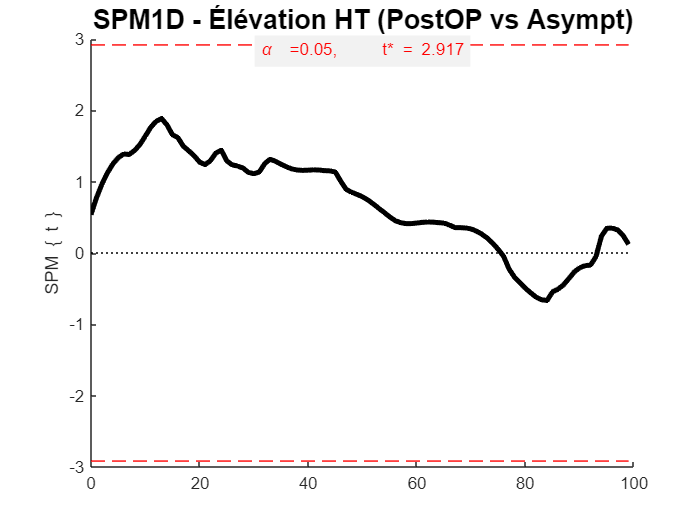


% === Test SPM1D entre PostOP et Asymptomatiques ===
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Statistics\spm1dmatlab-master'));

spm = spm1d.stats.ttest2(HT_data_postop, HT_data_asymp); % T test indépendant
spmi = spm.inference(0.05, 'two_tailed', true, 'interp', true);

figure;
spmi.plot();
spmi.plot_threshold_label();
spmi.plot_p_values();
title('SPM1D - Élévation HT (PostOP vs Asympt)', 'FontSize', 16);

**Comparasion asymptomatique vs pré**

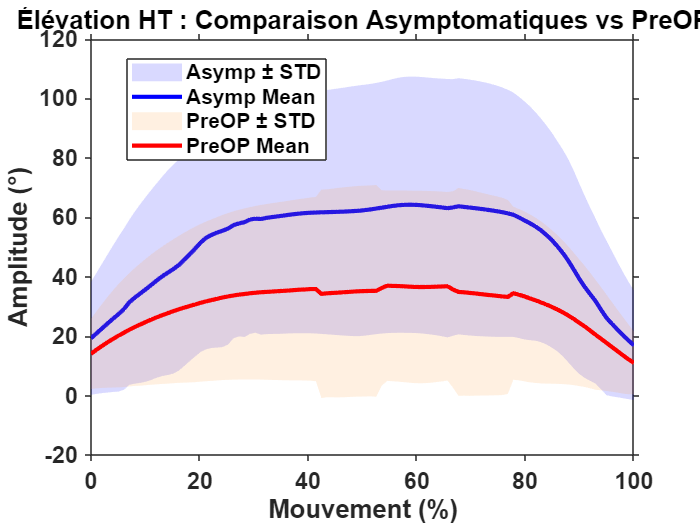

% === Chargement des deux jeux de données ===
load('all_angles_statistics_Asymptomatic.mat'); % Données Asymptomatiques
asymp_data = all_data;

load('all_angles_statistics_Pre_operatoire.mat'); % Données PreOP
preop_data = all_data;

x_new = linspace(0, 100, 100);

% === Moyennes combinées droite + gauche ===

% Asymptomatiques
asymp_right_mean = asymp_data.combined.right.HT.Elevation_globale.mean_deg;
asymp_right_std  = asymp_data.combined.right.HT.Elevation_globale.std_deg;

asymp_left_mean = asymp_data.combined.left.HT.Elevation_globale.mean_deg;
asymp_left_std  = asymp_data.combined.left.HT.Elevation_globale.std_deg;

asymp_mean = (asymp_right_mean + asymp_left_mean) / 2;
asymp_std  = (asymp_right_std + asymp_left_std) / 2;

% PreOP
preop_right_mean = preop_data.combined.right.HT.Elevation_globale.mean_deg;
preop_right_std  = preop_data.combined.right.HT.Elevation_globale.std_deg;

preop_left_mean = preop_data.combined.left.HT.Elevation_globale.mean_deg;
preop_left_std  = preop_data.combined.left.HT.Elevation_globale.std_deg;

preop_mean = (preop_right_mean + preop_left_mean) / 2;
preop_std  = (preop_right_std + preop_left_std) / 2;

% === Affichage combiné ===
figure;
hold on;
title('Élévation HT : Comparaison Asymptomatiques vs PreOP', 'FontSize', 18, 'FontWeight', 'bold');

% Zone bleue clair : ± std Asymp
fill([x_new fliplr(x_new)], ...
     [asymp_mean' + asymp_std' fliplr(asymp_mean' - asymp_std')], ...
     'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

plot(x_new, asymp_mean, 'b-', 'LineWidth', 2.5, 'DisplayName', 'Asymptomatiques');

% Zone orange clair : ± std PreOP
fill([x_new fliplr(x_new)], ...
     [preop_mean' + preop_std' fliplr(preop_mean' - preop_std')], ...
     [1 0.6 0.2], 'FaceAlpha', 0.15, 'EdgeColor', 'none');

plot(x_new, preop_mean, 'Color', 'r', 'LineWidth', 2.5, 'DisplayName', 'PreOP');

xlabel('Mouvement (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude (°)', 'FontSize', 14, 'FontWeight', 'bold');
legend({'Asymp ± STD', 'Asymp Mean', 'PreOP ± STD', 'PreOP Mean'}, 'Location', 'best');
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out');
box on;

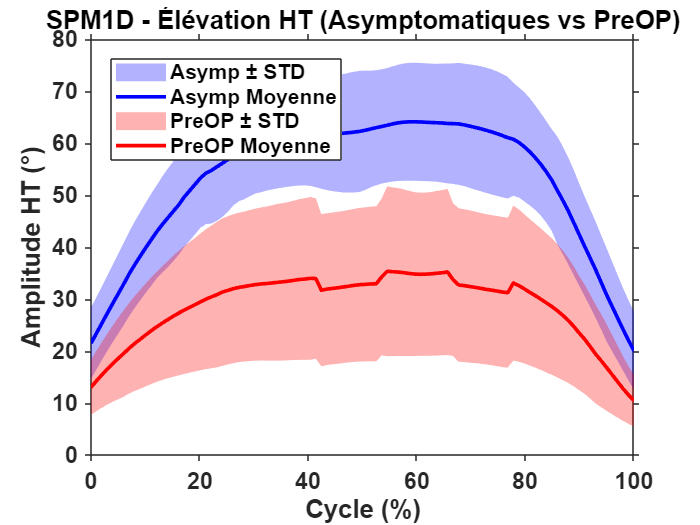


% === Configuration des sujets et côtés ===
asymp_subjects = arrayfun(@(i) sprintf('A%d', i), 1:41, 'UniformOutput', false);
preop_subjects = {'S1','S2','S3','S4','S5','S6','S7','S8','S9','S10','S11','S12','S13'};

sides_asymp = containers.Map( ...
    {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10', ...
     'A11','A12','A13','A14','A15','A16','A17','A18','A19','A20', ...
     'A21','A22','A23','A24','A25','A26','A27','A28','A29','A30', ...
     'A31','A32','A33','A34','A35','A36','A37','A38','A39','A40','A41'}, ...
    {'right','right','left','left','right','left','right','left','left','right', ...
     'left','left','left','left','left','left','left','left','left','left', ...
     'left','left','left','left','left','left','left','left','left','left', ...
     'left','left','left','left','left','left','left','left','left','left','left'});

sides_preop = containers.Map( ...
    {'S1','S2','S3','S4','S5','S6','S7','S8','S9','S10','S11','S12','S13'}, ...
    {'right','right','right','right','left','right','right','left','right','left', ...
     'right','right','left'});

% === Initialisation des matrices ===
HT_data_asymp = [];
HT_data_preop = [];

% Extraction Asymptomatiques
for i = 1:length(asymp_subjects)
    subj = asymp_subjects{i};
    side = sides_asymp(subj);
    try
        angle = asymp_data.subjects.(subj).combined.(side).HT.Elevation_globale.mean_deg;
        HT_data_asymp(i, :) = angle(:)';
    catch
        warning('Données manquantes pour %s (%s)', subj, side);
    end
end

% Extraction PreOP
for i = 1:length(preop_subjects)
    subj = preop_subjects{i};
    side = sides_preop(subj);
    try
        angle = preop_data.subjects.(subj).combined.(side).HT.Elevation_globale.mean_deg;
        HT_data_preop(i, :) = angle(:)';
    catch
        warning('Données manquantes pour %s (%s)', subj, side);
    end
end

% === Visualisation comparative ===
x_new = linspace(0, 100, size(HT_data_preop, 2));

mean_asymp = mean(HT_data_asymp, 1);
std_asymp  = std(HT_data_asymp, 0, 1);

mean_preop = mean(HT_data_preop, 1);
std_preop  = std(HT_data_preop, 0, 1);

figure;
hold on;

fill([x_new fliplr(x_new)], ...
     [mean_asymp + std_asymp fliplr(mean_asymp - std_asymp)], ...
     'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x_new, mean_asymp, 'b-', 'LineWidth', 2.2);

fill([x_new fliplr(x_new)], ...
     [mean_preop + std_preop fliplr(mean_preop - std_preop)], ...
     'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x_new, mean_preop, 'Color', 'r', 'LineWidth', 2.2);

xlabel('Cycle (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude HT (°)', 'FontSize', 14, 'FontWeight', 'bold');
title('SPM1D - Élévation HT (Asymptomatiques vs PreOP)', 'FontSize', 16, 'FontWeight', 'bold');
legend({'Asymp ± STD', 'Asymp Moyenne', 'PreOP ± STD', 'PreOP Moyenne'}, 'Location', 'best');
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out');
box on;

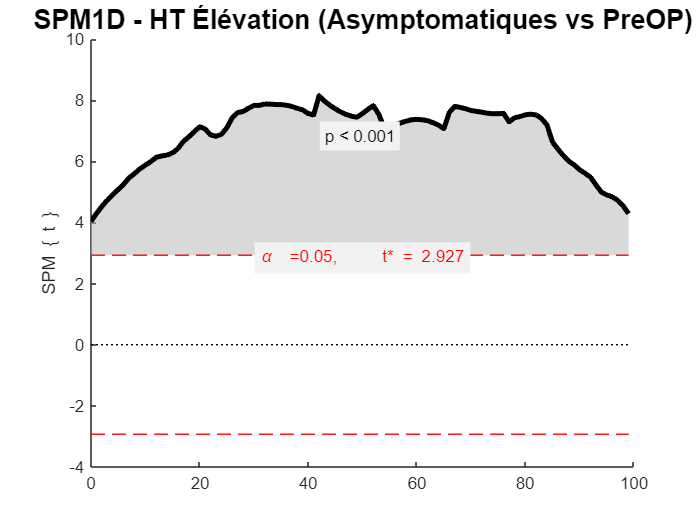


% === Test SPM1D (indépendant) ===
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Statistics\spm1dmatlab-master'));

spm = spm1d.stats.ttest2(HT_data_asymp, HT_data_preop); % Test indépendant
spmi = spm.inference(0.05, 'two_tailed', true, 'interp', true);

figure;
spmi.plot();
spmi.plot_threshold_label();
spmi.plot_p_values();
title('SPM1D - HT Élévation (Asymptomatiques vs PreOP)', 'FontSize', 16);

**Comparasion pré vs post**

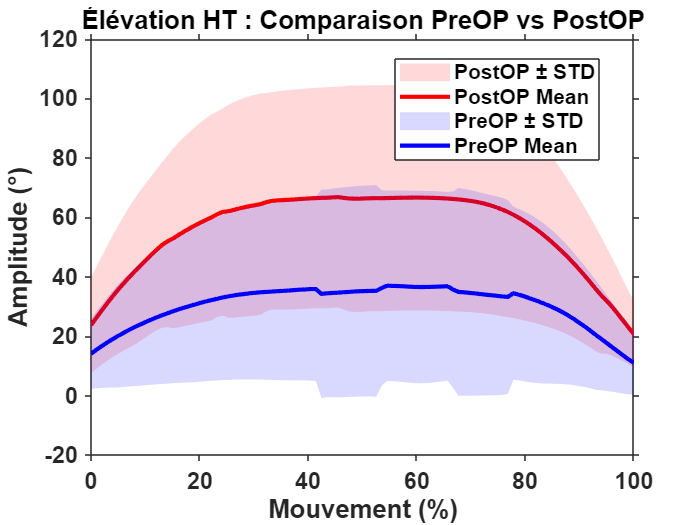

% === Chargement des deux jeux de données ===
load('all_angles_statistics_Post_operatoire.mat'); % Données PostOP
postop_data = all_data;

load('all_angles_statistics_Pre_operatoire.mat'); % Données PreOP
preop_data = all_data;

x_new = linspace(0, 100, 100);

% === Moyennes combinées droite + gauche ===

% PostOP
postop_right_mean = postop_data.combined.right.HT.Elevation_globale.mean_deg;
postop_right_std  = postop_data.combined.right.HT.Elevation_globale.std_deg;

postop_left_mean = postop_data.combined.left.HT.Elevation_globale.mean_deg;
postop_left_std  = postop_data.combined.left.HT.Elevation_globale.std_deg;

postop_mean = (postop_right_mean + postop_left_mean) / 2;
postop_std  = (postop_right_std + postop_left_std) / 2;

% PreOP
preop_right_mean = preop_data.combined.right.HT.Elevation_globale.mean_deg;
preop_right_std  = preop_data.combined.right.HT.Elevation_globale.std_deg;

preop_left_mean = preop_data.combined.left.HT.Elevation_globale.mean_deg;
preop_left_std  = preop_data.combined.left.HT.Elevation_globale.std_deg;

preop_mean = (preop_right_mean + preop_left_mean) / 2;
preop_std  = (preop_right_std + preop_left_std) / 2;

% === Affichage combiné ===
figure;
hold on;
title('Élévation HT : Comparaison PreOP vs PostOP', 'FontSize', 18, 'FontWeight', 'bold');

% Zone rouge clair : ± std PostOP
fill([x_new fliplr(x_new)], ...
     [postop_mean' + postop_std' fliplr(postop_mean' - postop_std')], ...
     'r', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

plot(x_new, postop_mean, 'r-', 'LineWidth', 2.5, 'DisplayName', 'PostOP Mean');

% Zone bleue clair : ± std PreOP
fill([x_new fliplr(x_new)], ...
     [preop_mean' + preop_std' fliplr(preop_mean' - preop_std')], ...
     'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

plot(x_new, preop_mean, 'b-', 'LineWidth', 2.5, 'DisplayName', 'PreOP Mean');

xlabel('Mouvement (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude (°)', 'FontSize', 14, 'FontWeight', 'bold');
legend({'PostOP ± STD', 'PostOP Mean', 'PreOP ± STD', 'PreOP Mean'}, 'Location', 'best');
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out');
box on;

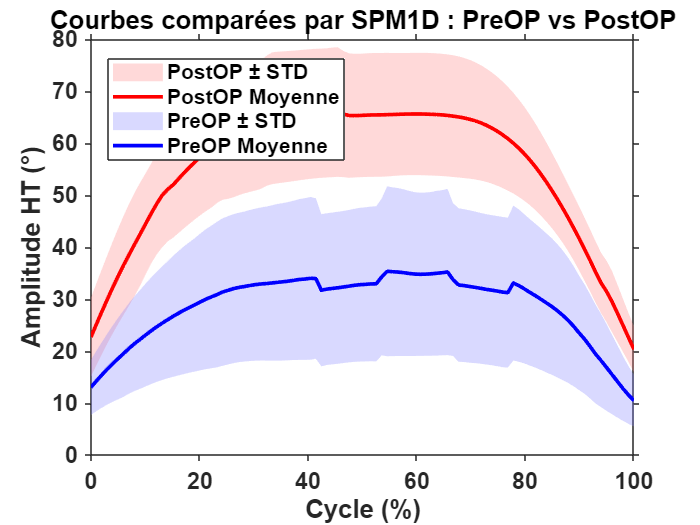


% === Sujets et côtés ===
preop_subjects = {'S1','S2','S3','S4','S5','S6','S7','S8','S9','S10','S11','S12','S13'};
postop_subjects = preop_subjects; % mêmes sujets

sides = containers.Map( ...
    {'S1','S2','S3','S4','S5','S6','S7','S8','S9','S10','S11','S12','S13'}, ...
    {'right','right','right','right','left','right','right','left','right','left', ...
     'right','right','left'});

% === Extraction des courbes ===
HT_data_preop = [];
HT_data_postop = [];

for i = 1:length(preop_subjects)
    subj = preop_subjects{i};
    side = sides(subj);
    try
        angle_pre = preop_data.subjects.(subj).combined.(side).HT.Elevation_globale.mean_deg;
        angle_post = postop_data.subjects.(subj).combined.(side).HT.Elevation_globale.mean_deg;
        HT_data_preop(i, :) = angle_pre(:)';
        HT_data_postop(i, :) = angle_post(:)';
    catch
        warning('Données manquantes pour %s (%s)', subj, side);
    end
end

% === Visualisation des moyennes ===
x_new = linspace(0, 100, size(HT_data_postop, 2));

mean_postop = mean(HT_data_postop, 1);
std_postop  = std(HT_data_postop, 0, 1);

mean_preop = mean(HT_data_preop, 1);
std_preop  = std(HT_data_preop, 0, 1);

figure;
hold on;

fill([x_new fliplr(x_new)], ...
     [mean_postop + std_postop fliplr(mean_postop - std_postop)], ...
     [1 0.5 0.5], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x_new, mean_postop, 'r-', 'LineWidth', 2.2);

fill([x_new fliplr(x_new)], ...
     [mean_preop + std_preop fliplr(mean_preop - std_preop)], ...
     [0.5 0.5 1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x_new, mean_preop, 'b-', 'LineWidth', 2.2);

xlabel('Cycle (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude HT (°)', 'FontSize', 14, 'FontWeight', 'bold');
title('Courbes comparées par SPM1D : PreOP vs PostOP', 'FontSize', 16, 'FontWeight', 'bold');
legend({'PostOP ± STD', 'PostOP Moyenne', 'PreOP ± STD', 'PreOP Moyenne'}, 'Location', 'best');
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out');
box on;

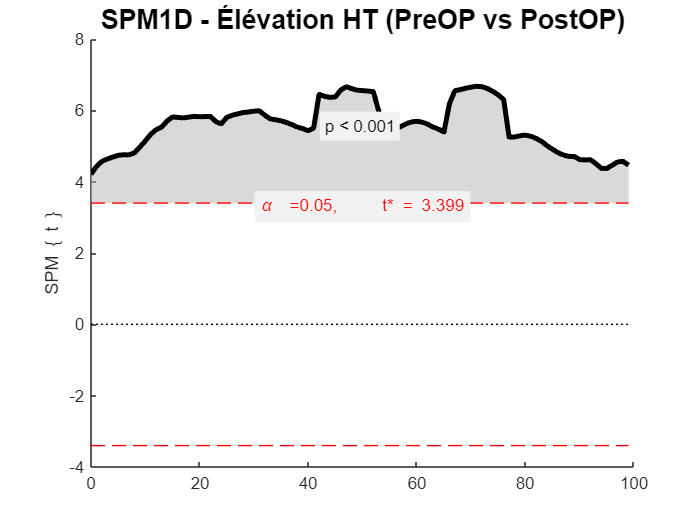


% === Test SPM1D pour données appariées ===
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Statistics\spm1dmatlab-master'));

spm = spm1d.stats.ttest_paired(HT_data_postop, HT_data_preop); % Test apparié
spmi = spm.inference(0.05, 'two_tailed', true, 'interp', true);

figure;
spmi.plot();
spmi.plot_threshold_label();
spmi.plot_p_values();
title('SPM1D - Élévation HT (PreOP vs PostOP)', 'FontSize', 16);